# K-means Clustring

**Introduction**

K-means clustering is an unsupervised learning method used for classifying data into distinct groups based on their similarities. It is particularly useful in scenarios where you need to identify distinct categories or groups within your data. K-means clustering aims to partition 'n' observations into 'k' clusters, focusing on minimizing the distance to the group's mean. 

**Tutorial Objective**

This tutorial aims to manually implement the k-means clustering algorithm to partition a dataset into k clusters. You can thik that the generate dataset  in this tutorial represents the firing rates of two neurons in response to different stimuli.

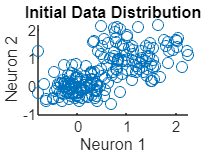

% Set the random seed for reproducibility

% Generate  data representing two clusters
N1 = 0.3 * randn(100, 2);  % Data from neuron 1
N2 = 0.5 * randn(100, 2) + 1;  % Data from neuron 2 with a shift
population = [N1; N2];  % Combine data into one dataset; a population of 2 neurons

% Plot the initial data to visualize the clusters
figure;
scatter(population(:,1), population(:,2));
title('Initial Data Distribution');
xlabel('Neuron 1');
ylabel('Neuron 2');

There are many algorithem to do this but we implement one of the simplest one. First we choose two random points in our data as our cluster's centers and assign each data point to that cluster according to the distance between cluster's center and the data point then we compute an updated value of center by calculating cluster's mean. We repeat the process to reach to a satisfactory condition.


% Initialize k-means parameters
k = 2;  % Number of clusters
maxIterations = 100;  % Maximum number of iterations to prevent infinite loops
tolerance = 0.0001;  % Convergence criterion

% Randomly select initial centroids
initialIndices = randperm(size(population, 1), k);
centroids = population(initialIndices, :)

centroids =    -0.0464   -0.3976
   -0.3494   -0.1810
   -0.1668   -0.0342
    0.2306   -0.3662
    1.7924    1.4361




% Start the k-means clustering process
for iter = 1:maxIterations
    % Calculate distances from each point to each centroid
    distances = arrayfun(@(i) sum((population - centroids(i, :)).^2, 2), 1:k, 'UniformOutput', false);
    distances = cell2mat(distances);

    % Assign each data point to the closest cluster
    [~, clusterAssignment] = min(distances, [], 2);

    % Update centroids based on mean of assigned data points
    newCentroids = arrayfun(@(i) mean(population(clusterAssignment == i, :), 1), 1:k, 'UniformOutput', false);
    newCentroids = reshape(cell2mat(newCentroids),2,k)';


    % Check for convergence (if centroids do not change)
    if max(max(abs(newCentroids - centroids))) < tolerance
        disp('Convergence reached.');
        break;
    end
    centroids = newCentroids;

    % Optional: Display the process
    fprintf('Iteration %d, centroids updated.\n', iter);
end

Iteration 1, centroids updated.
Iteration 2, centroids updated.
Iteration 3, centroids updated.
Iteration 4, centroids updated.
Iteration 5, centroids updated.
Iteration 6, centroids updated.
Iteration 7, centroids updated.
Iteration 8, centroids updated.
Iteration 9, centroids updated.
Iteration 10, centroids updated.
Iteration 11, centroids updated.
Iteration 12, centroids updated.
Iteration 13, centroids updated.
Iteration 14, centroids updated.
Iteration 15, centroids updated.


Convergence reached.


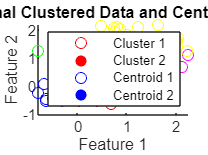


% Display final clusters and centroids
figure;
hold on;
colors = 'rbgmyk';  % Colors for different clusters
for i = 1:k
    scatter(population(clusterAssignment == i, 1), population(clusterAssignment == i, 2), 'MarkerEdgeColor', colors(i));
    scatter(centroids(i, 1), centroids(i, 2), 'filled', 'MarkerFaceColor', colors(i));
end
title('Final Clustered Data and Centroids');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Cluster 1', 'Cluster 2', 'Centroid 1', 'Centroid 2');
hold off;

You can try different values of k and observe how the clustering results change.